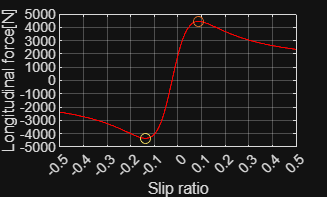

% Longitudinal Force vs SLip Ratio, based on Magic Formula
clear
load("mfparams_2.mat");
CoeffLong = Tire_Coefficients(mfparams, 'c_long');
SFLong = Tire_Scaling_Factors(mfparams, 'sf_long');

%% main settings
%pressure [bar]
pressure = 0.7;
%camber angle
gamma = 0; 
% Normal force
Fz = 2000;   
%slip ratio
kappa = -0.5:0.0005:0.5; 


%plot
Fx0 = LongitudinalMF(CoeffLong,SFLong,kappa,Fz,gamma,pressure);
plot(kappa,Fx0, "r");
hold on

%plot settings
xlabel("Slip ratio");
xticks(-0.50:0.1:0.50);
xlim([-0.50 0.50]);

ylabel("Longitudinal force[N]");
yticks(-10000:1000:10000)

grid

% max and min
[FxMax, FxMaxIdx] = max(Fx0);
scatter(kappa(:,FxMaxIdx),FxMax);
kappaMax = kappa(FxMaxIdx);

[FxMin, FxMinIdx] = min(Fx0);
scatter(kappa(:,FxMinIdx),FxMin);

kappaMin = kappa(FxMinIdx);

